
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }5$$


# 
$$DC\text{ }Motor\text{ }Speed\text{ }Control\text{ }with\text{ }Full\text{ }State\text{ }Feedback$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID = '260741964';
Students(2).Name = 'Nayem Alem';
Students(2).ID = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, we will use state feedback to control the angular speed of DC motor.

The lab uses the MATLAB interface to the DC Motor. To verify that the hardware is working, run the following (You can ignore the warnings, but you shouldn't have any errors)

Motor = QnetDCMotor();

## **1. A state space representation of DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

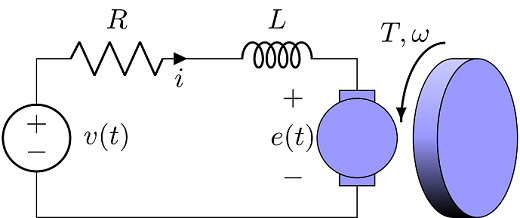

We have seen in the previous labs how the transfer function between the voltage $v$ and the angular velocity of the shaft $\omega$ of this DC Motor can be approximated to a first order system.

In this lab, we will model the DC motor using the armature current $i$ and the angular speed $\omega$. The dynamics of the DC motor are given by the following two coupled differential equations:


$$ J \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \frac{d i}{dt} + R i = v - K_e \omega $$


where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor model by the following state space representation


$$ \frac{d}{dt}x(t) = \left[\matrix{ -\frac{b}{J} & \frac{K_t}{J} \cr
-\frac{K_e}{L} & -\frac{R}{L} } \right] x(t) + \left[\matrix{ 0 \cr
\frac{1}{L} } \right] v(t) $$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \left[\matrix{ \omega(t) \cr i(t) } \right] $$


## *Question 1 (1 mark)*

Write the state space representation of the DC Motor (Only A and B matrices).

A = [-Param.b/Param.J Param.Kt/Param.J; -Param.Ke/Param.L -Param.R/Param.L]

A =    1.0e+03 *

   -0.0000    1.7000
   -0.0019   -0.4667



B = [0; 1/Param.L]

B =          0
   55.5556


## **2. Desired specifications**

The objective of this lab is to track a step signal $\omega_{ref}$ defined by the following

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
time = 0:dt:T; % Time array
TStart = 5; % Step start
wRef = zeros(size(time));
wRef(time < TStart) = 25;
wRef(time >= TStart) = 75;

While satistfying the following requirements:

- Overshoot less than 10%.

- 5%-settling time less than 0.2 seconds.

- Steady state gain of 1 $\pm$ 5%.

The state space open-loop system is presented below.

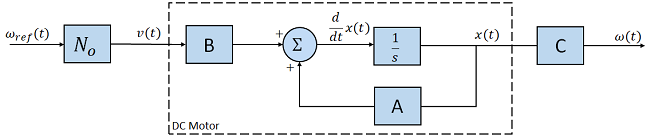

Note that if we think of the angular velocity $\omega(t)$ as the output, then


$$ \omega(t) = C x(t) $$


where $C = \left[\matrix{1 & 0} \right]$. Thus, the transfer function from the voltage $v(t)$ to the angular speed $\omega(t)$ is given by


$$ G_o(s) = C (s I - A)^{-1} B $$


In `MATLAB`, we can compute the transfer function of a state space model using the function `tf`, as shown below.

C = [1, 0];
D = 0;

Go = ss(A, B, C, D)


Go =
 
  A = 
           x1      x2
   x1   -0.05    1700
   x2  -1.889  -466.7
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



tf(Go)


ans =
 
        9.444e04
  --------------------
  s^2 + 466.7 s + 3234
 
Continuous-time transfer function.



## *Question 2 (1 mark)*

From the state space model, identify the DC gain.

dcGainOL = [-C*inv(A)*B]

dcGainOL = 29.1996

Observe that the open loop system is a stable system. The DC Motor will follow a reference signal even without using a controller. However, the response will be determined by the eigenvalues of the open loop $A$ matrix (or equivalently, the poles of the open loop transfer function).

In other words, following an input $v_0$ the angular velocity $\omega$ will attain a steady angular velocity $\omega_{\infty} = DC_{gain} v_0$.

The gain $N_o$ is used to compensate for the open-loop DC gain, such as the total gain from $\omega_{ref}$ to $\omega$ is one.

## *Question 3 (1.5 marks)*

- Complete the following code to run the DC Motor in open-loop in such a way that the final value of angular velocity $\omega_{\infty}$ is equal to the desired angular velocity signal $\omega_{ref}$

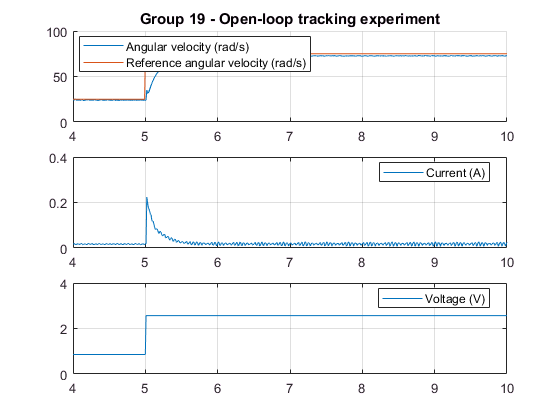

% Run the simulation
Motor.reset();
for n = 1:length(time)
    t_ = time(n);
    v_ = (wRef(n)/dcGainOL); % fill the value of the voltage v_
    Motor.drive(v_, t_, dt);
end
Motor.off();

% Get results of driving Qnet DC Motor
t = Motor.time(TStart-1, T);
v = Motor.voltage(TStart-1, T);
i = Motor.current(TStart-1, T);
w = Motor.velocity(TStart-1, T);

% Plot results
figure(1); clf;

subplot(3, 1, 1)
title(sprintf('Group %d - Open-loop tracking experiment', GroupeNum));
% Superpose the angular velocity and the the reference $\omega_{ref}$

hold on
plot(t,w)
plot(time, wRef)
hold off

legend('Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');

xlim([TStart - 1, T])
grid on

subplot(3, 1, 2)
% Plot current here

plot(t,i)
legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])
grid on

subplot(3, 1, 3)
% Plot voltage here
plot(t,v)
legend('Voltage (V)', 'location', 'best');
xlim([TStart - 1, T])
grid on

- Are the requirements satisfied in open-loop. Justify your answer

          No because the settling time is more than 0.2 seconds.Furthermore, the velocity at 0.2 seconds is 57.3 and this is not within 5% of the reference value. Hence, the requirements do not statisfy the open loop system.

## *3. Closed-loop state feedback for speed control*

The closed-loop system is presented in the following figure.

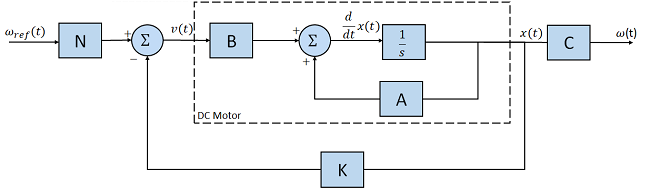

The full-state feedback control law is


$$v(t) = N\omega_{ref} - K x(t)$$


where $K$ is a 1 by 2 gain and $N$ is forward gain that will ensure achieving $\omega_{ref}$ at steady state.

Actually, this diagram is equivalent to an open-loop diagram but with a different state transition matrix $A_{cl} = A-BK$

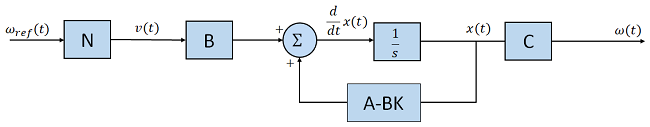

Doing a state feedback with gain $K$ is equivalent to changing the system dynamics from $A$ to $A-BK$. Recall that the eigenvalues of a state transition matrix $A$ are the poles of the system.

## *Question 5 (1 mark)*

What are the poles of state space system (A,B,C,D) describing the DC Motor. (Hint: `help eig`)

E = eig(Go)

E =    -7.0363
 -459.6804



p1 = E(1)

p1 = -7.0363

p2 = E(2)

p2 = -459.6804

We want to choose $K$ to specify the new poles of the closed-loop system $A-BK$ in a way that satisfies the specifications

- Overshoot less than 10%.

- 5%-settling time less than 0.2 seconds.

## *Question 6 (1 mark)*

Calculate the desired poles that satisfies the specifications (Use formula sheet for transient response of 2nd order system in myCourses if needed):

zeta = -log(1/10)/((pi*pi+(log(1/10))^2)^(0.5))

zeta = 0.5912

sigma = (3/0.2)

sigma = 15

wn = sigma/Zeta

wn = 25.3741


s=tf('s');
G = (wn^2)/(s^2+2*zeta*wn*s+wn^2)


G =
 
        643.8
  ------------------
  s^2 + 30 s + 643.8
 
Continuous-time transfer function.



X = pole (G)

X =  -15.0000 +20.4656i
 -15.0000 -20.4656i



p1d = X(1)

p1d =  -15.0000 +20.4656i


p2d = X(2)

p2d =  -15.0000 -20.4656i


## *3.1. Closed-loop simulation*

Instead of manual calculation of the value of the gain $K$ that place the poles of $A-BK$ at [p1d, p2d], we will use the `place` command to calculate the gain $K$

K = place(A, B, [p1d, p2d]);

## *Question 7 (1 mark)*

- The closed loop transfer function is


$$ G_c(s) = C (sI - (A-BK))^{-1} B $$


- What is the value of the DC gain of the closed loop system 

dcGainCL = -C*inv(A-B*K)*B

dcGainCL = 146.6887

- What is the value $N_c$ needed to compensate for the DC gain of the closed loop system

N = 1/dcGainCL;

- Complete the following to simulate speed control with state feedback that tracks the desired $\omega_{ref}$:

Gc = ss(A-B*K, B, C, D) % define the closed loop system


Gc =
 
  A = 
            x1       x2
   x1    -0.05     1700
   x2  -0.3779   -29.95
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% simulate closed loop
wSim = lsim(Gc, N*wRef, time);
iSim = lsim(ss(Gc.A, Gc.B, [0, 1], Gc.D), N*wRef, time);

figure(2); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - Closed-loop simulation', GroupeNum));
% superpose simulated angular velocity with the angular speed reference

hold on
plot(time,wSim)
plot(time, wRef)

hold off
legend('Simulated angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');

xlim([TStart - 1, T])
grid on

subplot(2, 1, 2)
% Plot simulated current here

legend('Simulated current (A)', 'location', 'best');

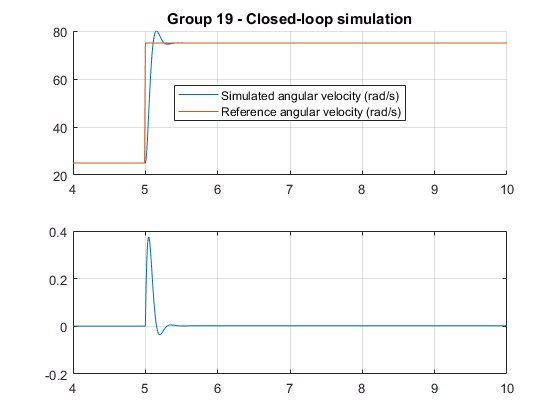

plot(time,iSim)
xlim([TStart - 1, T])
grid on

## *3.2. Closed-loop experiment*

In order to control the DC Motor we need to generate a discrete control law that achieves the desired poles. Converting the gains $K$ and $N$ to their equivalent discrete form involves the following steps

Go_d = c2d(Go, dt, 'zoh'); % get the equivalent discrete open-loop system
Kd = place(Go_d.A, Go_d.B, [exp(p1d*dt), exp(p2d*dt)]);
Nd = 1/(Go_d.C*(eye(2)-Go_d.A+Go_d.B*Kd)^(-1)*Go_d.B);

## *Question 8 (1.5 marks)*

- Complete the following to test the state feedback controller for tracking the desired $\omega_{ref}$:

% Run the simulation
Motor.reset();

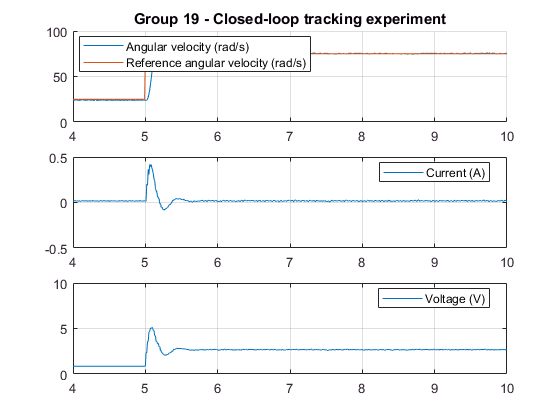

for n = 1:length(time)
    t_ = time(n);
    w_ = Motor.velocity(t_);
    i_ = Motor.current(t_);
    
    if (t_ < TStart)
        v_ = wRef(n)/dcGainOL;
    else
        v_ = Nd*wRef(n)-Kd*[w_; i_]; % Write the state feedback controller equation
    end
    Motor.drive(v_, t_, dt);
end
Motor.off();

% Get results of driving Qnet DC Motor

t = Motor.time(TStart-1, T);
v = Motor.voltage(TStart-1, T);
i = Motor.current(TStart-1, T);
w = Motor.velocity(TStart-1, T);

% Plot results

figure(3); clf;

subplot(3, 1, 1)
title(sprintf('Group %d - Closed-loop tracking experiment', GroupeNum));

hold on
plot(t,w)
plot(time, wRef)

hold off
% Superpose angular velocity and the velocity reference

legend('Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])

grid on

subplot(3, 1, 2)
% Plot current here

plot(t,i)
legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])

grid on

subplot(3, 1, 3)
% Plot voltage here

plot(t,v)
legend('Voltage (V)', 'location', 'best');
xlim([TStart - 1, T])
grid on

- Do we satisfy the requirements. Justify your answer

            No the overshoot is 30%, which is way larger than 10%. Hence this does not satisfy the requirements.

## *Question 9 (1 mark)*

Can you tune the value of the gain $N_d$ to get better perfermance (You can also tune $K_d$ if needed).

Nd = Nd;

% Run the simulation

Motor.reset();

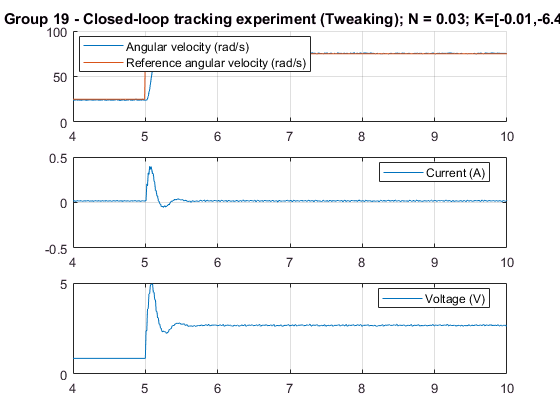

for n = 1:length(time)
    t_ = time(n);
    w_ = Motor.velocity(t_);
    i_ = Motor.current(t_);
    
    if (t_ < TStart)
        v_ = wRef(n)/dcGainOL;
    else
        v_ = Nd*wRef(n)-Kd*[w_; i_]; % Write the state feedback controller equation
    end
    Motor.drive(v_, t_, dt);
end
Motor.off();


% Get results of driving Qnet DC Motor

t = Motor.time(TStart-1, T);
v = Motor.voltage(TStart-1, T);
i = Motor.current(TStart-1, T);
w = Motor.velocity(TStart-1, T);

% Plot results
figure(4); clf;

subplot(3, 1, 1)
title(sprintf('Group %d - Closed-loop tracking experiment (Tweaking); N = %04.2f; K=[%04.2f,%04.2f]', ...
    GroupeNum, Nd, Kd));
% Superpose the angular velocity and the velocity reference

hold on
plot(t,w)
plot(time, wRef)
hold off

legend('Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])

grid on

subplot(3, 1, 2)
% Plot current here

plot(t,i)
legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])

grid on

subplot(3, 1, 3)

% Plot voltage here

plot(t,v)
legend('Voltage (V)', 'location', 'best');
xlim([TStart - 1, T])

grid on